# Answer regarding the fitting stability of the parameter *N*, describing the rate of saturation of spatial information

Dear Reviewer,

You requested from us the following analysis to confirm that there are no systematic biases in our analysis that would incorrectly result in a reported ensemble scale of information saturation that scales with the number of measured neurons instead of being invariant to them. Quoted below:

*Isn’t I a bit suspicious that the saturation is approached for population sizes that exactly match the measured population sizes? I would suggest validating this with synthetic data, using population of different sizes (e.g. 500 to 50,000) where in all cases information saturates at ~500 neurons, “measuring” only ~500 of those, and testing that the inferred saturation point is consistently ~500, regardless of full population size. And conversely, generating synthetic data that saturate at different N, and testing that the analysis method recovers close to the true value.*

In response to your comment, we have completed an analysis consisting of:

- The development of a simple synthetic model of a population of spatially tuned neurons, where the population size can be tuned and information saturation can be induced with tunable input noise.

- Using our curve fitting procedure, verifying that the estimated *N* value is stable using both 500 neurons and 2000 neurons in the population.

- Using our curve fitting procedure, verifying that the estimated asymptotic IMSE value using 500 neurons is consistent with the near-asymptotic IMSE value using 10,000 neurons for a range of input noise strengths, and comparing the estimated *N* values to the respective *N* values inferred from the IMSE of the 10,000 neuron population.

## A Synthetic Model of a Population of Spatially Tuned Neurons

We chose a simple model of position-encoding neurons with the following parameters, some of which are meant to reflect the experiment:

- Poisson neurons with a maximal firing rate of 0.05.

- Gaussian place fields with a full-width-half-max of 30cm, centered randomly on a 120cm track.

- A sinusoidal simulated mouse trajectory, spanning the length of the track, with a maximal velocity of 30cm/s.

- Simulated sessions sampled at 20Hz, spanning 30 minutes.

- Gaussian input noise of standard deviation 10cm (or a given value), in order to simulate information-limiting correlations.

The model simulates a 30 minute experiment during which a mouse runs on a 120cm long linear track. We constructed the simulated neuronal activity using a set of gaussian place fields (Fig 1) belonging to a set of neurons that respond to a simulated trajectory (Fig 2, top). Since the neurons are all independent of each other given the position, we introduced information-limiting correlations by applying gaussian noise to the position signal *prior* to the encoding step. Later, when we apply decoders to the simulated neuronal activity data (Fig 2, bottom), the decoder attempts to predict the position without the added noise. The input noise causes the accuracy of the decoder to saturate at a certain value in the limit of an infinite neuronal ensemble size. Our goal is to demonstrate that our estimates of the rate of saturation, namely, the parameter *N* as described in our paper, are not affected by the size of the neuronal ensemble that we are able to measure. Particularly, we will show that a small neuronal ensemble of 500 neurons produces an estimate of *N* that is consistent with an estimate of *N* coming from a large neuronal ensemble of 2000 neurons.

### Neuronal tuning properties

max_rate = 0.05;
track_len = 120;
n_cells = 500;
hwhm = 15;

field_std = hwhm * 2 / 2.355;
m = sort(rand(n_cells, 1)) * track_len;
rate_func = @(x) max_rate.*exp(-((x-m)./field_std).^2./2);

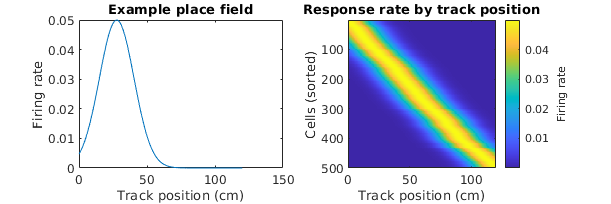

x_examples = 0:0.5:120;
rate_ex = rate_func(x_examples);

figure('Position', [394   483   611   204]);
subplot(1,2,1);
plot(x_examples, rate_ex(123,:));
xlabel 'Track position (cm)'
ylabel 'Firing rate'
title 'Example place field'
xlim([0 120]);

subplot(1,2,2);
imagesc(x_examples, 1:n_cells, rate_ex);
hb = colorbar; hb.Label.String = 'Firing rate';
xlabel 'Track position (cm)'
ylabel 'Cells (sorted)'
title 'Response rate by track position'

#### Figure 1: Simulated neuronal place fields

**(Left) **A simulated place field for an example neuron. The neuron's firing rate is a gaussian function of the track position. The center of the place field for each simulated neuron is a random position on the track, drawn uniformly. The full-width at half maximum (FWHM) is set to 30 cm for all the neurons. The maximal firing rate of each neuron is set to 0.05.

**(Right)** A heatmap of the firing rate functions of all the neurons in the simulated ensemble, as functions of the track position, sorted by their preferred firing position. With 500 neurons the place fields tile the entire track.

### Example synthetic neuronal activity

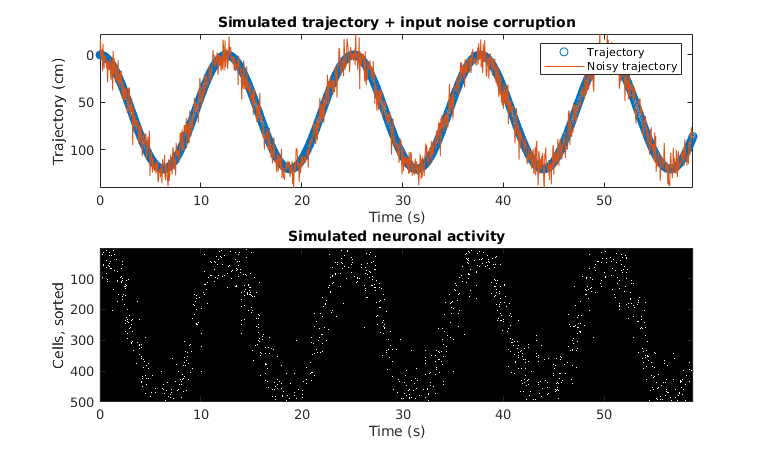

dt = seconds(1/20);
sess_time = hours(0.5);
max_v = 30; %cm/s

t = seconds(seconds(0):dt:sess_time); %s
x_traj = track_len .* sin(max_v./track_len .* t).^2;

noise_sigma = 10; %cm
input_noise = noise_sigma*randn(size(x_traj));

figure('Position', [409   273   766   452]);
subplot(2,1,1);
plot(t, x_traj, 'o');
hold on;
plot(t, x_traj + input_noise);
xlabel 'Time (s)'
ylabel 'Trajectory'
legend 'Trajectory' 'Noisy trajectory'
axis ij

%xlim([289.8 359.3])
xlim([-0.0 58.8])
ylim([-22 140])
title 'Simulated trajectory + input noise corruption'
response_sample = @(x) poissrnd(rate_func(x));
alg = fastpnb;

X_noise = response_sample(x_traj + input_noise);

%figure('Position', [112 520 1563 425]);
subplot(2,1,2);
imagesc(t, 1:n_cells, X_noise ~= 0);
%colorbar;

xlim([-0.0 58.8])
xlabel 'Time (s)'
ylabel 'Cells, sorted'
title 'Simulated neuronal activity'
colormap gray

subplot(2,1,1)
ylabel('Trajectory (cm)')

#### Figure 2: A simulated linear track experiment

**(Top) **Part of a 30-minute long simulated mouse trajectory on a linear track. Showing the true trajectory (in blue), as well as the same trajectory corrupted by gaussian input noise with a std. dev. of 10cm (in red). Instead of using the position values of the true trajectory as the input to our simulated ensemble of independent Poisson neurons, we used the noise-corrupted trajectory with the purpose of causing information-limiting noise correlations when trying to decode the true trajectory from the set of neuronal responses. Note that these do not represent decoded trajectories, but rather the inputs into the generative model of neuronal activity.

**(Bottom) **A sample of a set of simulated neuronal responses, sorted by the preferred firing position of each neuron. Each neuron fires according to an inhomogeneous Poisson random variable, dependent on the position, with a firing rate that follows the place field of that neuron (Fig. 1).

## Decoding spatial information from a small and large ensemble

To determine the information saturation rate of our simulated neuronal ensemble, we sampled the neuronal subset sizes at logarithmic intervals, removing samples that were in the nonlinear regime of the inverse mean squared classification error relative to the input noise in the absence of output noise (Appendix A). Since these data exhibited a clearly nonzero y-intercept (unlike the experimental data), we used a parametric fit containing a y-intercept term: $I\left(n\right)=\frac{I_0 n}{1+\frac{n}{N}}+c$. According to this model, $\lim_{n\to \infty } I\left(n\right)=I_{0\;} N+c$. The following results compare the parametric fit results from the inverse mean squared error (IMSE) of decoding spatial position across two population sizes of 500 and 2,000 neurons (Fig. 3). We used Poisson naive Bayes as the decoder, by discretizing the position into 20 bins as in the paper, but ignoring the running direction for simplicity (our model does not encode the running direction). The IMSE is defined as in the paper.

n_size_low = 500;
n_size_high = 16000;

[n_low, mse_low, ~, fr_low, gof_low] = general_decoding_curve('n_cells', n_size_low, 'noise_sigma', noise_sigma, 'linear_only', true, 'approx_samp', 50);

[n_high, mse_high, ~, fr_high, gof_high] = general_decoding_curve('n_cells', n_size_high, 'noise_sigma', noise_sigma, 'linear_only', true, 'approx_samp', 50);

[n_, mse_] = general_decoding_curve('n_cells', 50, 'noise_sigma', noise_sigma, 'linear_only', true, 'approx_samp', 50, 'max_rate', 2);
asymp_imse = 1./mean(mse_(:,end));

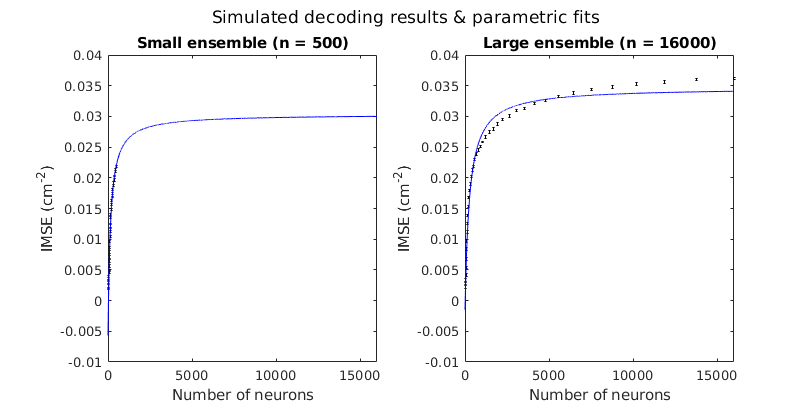

figure('Position', [394   483   811   404]);
ax(1) = subplot(1,2,1);
ep(n_low, 1./mse_low, 'k');
hold on;
plot(1:max(n_high), fr_low(1:max(n_high)), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title(sprintf('Small ensemble (n = %d)', n_size_low));
%yline(asymp_imse);

ax(2) = subplot(1,2,2);
ep(n_high, 1./mse_high, 'k');
hold on;
plot(1:max(n_high), fr_high(1:max(n_high)), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title(sprintf('Large ensemble (n = %d)', n_size_high));
%yline(asymp_imse);

linkaxes(ax);

Utils.printto('events_figs/stability_analysis', 'small_and_large_fits.pdf');
sgtitle 'Simulated decoding results & parametric fits'

#### Figure 3a: Decoding results as a function of ensemble size and parametric fits

**(Left) **Decoding performance at various sub-ensemble sizes from an ensemble of 500 neurons (black). The decoding scheme, including cross-validation, follows the methods used in the paper, except for using a Poisson naive Bayes model in place of the SVM ensemble. The error bars show 95% CIs over 16 random subsets and train-test divisions. Also showing the parametric fit curve, extended up to 2000 neurons (blue).

**(Right)** The same results as in the left plot, but using an ensemble with 2000 neurons. The two ensemble sizes produce consistent results.

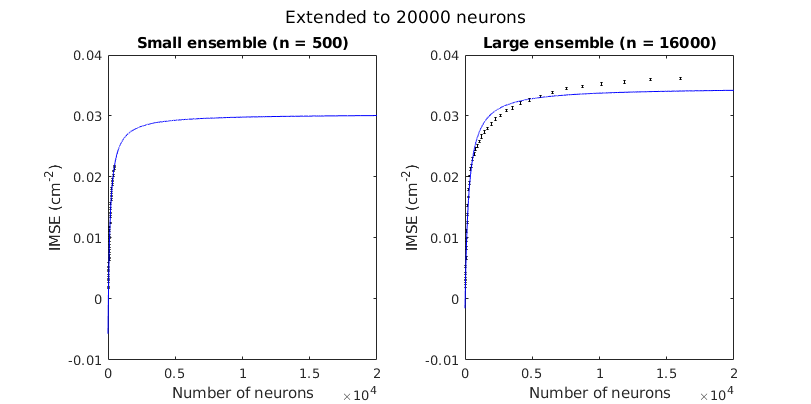

figure('Position', [394   483   811   404]);
ax(1) = subplot(1,2,1);
ep(n_low, 1./mse_low, 'k');
hold on;
huge_n = 2e4;
plot(1:huge_n, fr_low(1:huge_n), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title(sprintf('Small ensemble (n = %d)', n_size_low));
%yline(asymp_imse);

ax(2) = subplot(1,2,2);
ep(n_high, 1./mse_high, 'k');
hold on;
plot(1:huge_n, fr_high(1:huge_n), 'b');
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title(sprintf('Large ensemble (n = %d)', n_size_high));
%yline(asymp_imse);

linkaxes(ax);
Utils.printto('events_figs/stability_analysis', 'small_and_large_fits_extended.pdf');
sgtitle(sprintf('Extended to %d neurons', huge_n));

#### Figure 3b: The same plots as in Fig 3a, but with the fitted curve extended up to 10,000 neurons to show the predicted very large ensemble size results using both the small and large ensemble sizes.

### The estimates of *N* from the two ensemble sizes are in agreement

The confidence intervals for the fitted values of *N* overlap (Figure 4). Contrary to the Reviewer's concern, we did not observe that the fitted *N* value increases on a larger ensemble.

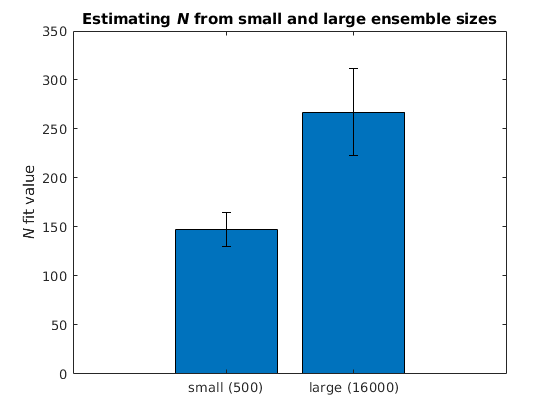

figure;
c = {sprintf('small (%d)', n_size_low), sprintf('large (%d)', n_size_high)};
N_vals = [fr_low.N fr_high.N];
N_conf = [get_ci(fr_low,'N') get_ci(fr_high, 'N')];
barerr([1 2], N_vals, N_conf);
ylabel '{\itN} fit value'
set(gca, 'XTickLabel', c);
title 'Estimating {\itN} from small and large ensemble sizes'

#### Figure 4: The fitted *N* values from the small and large ensemble sizes are consistent

The parametric fit procedure identifies the optimal estimate for the parameter *N* (bar height) and provides 95% confidence intervals (error bars). We show the results on the small (500 neurons) and large (2,000 neurons) simulated ensembles. The confidence intervals overlap, indicating that the two results are consistent. In particular, there is no bias towards a larger estimate of *N* in the larger ensemble.

## Decoding from the small ensemble with varying levels of input noise

The following test confirms that the parametric fit to $I\left(n\right)=\frac{I_0 n}{1+\frac{n}{N}}+c$ is able to characterize a range of input noise values, which in turn correspond to a range of *N* values reflecting smaller or larger saturation rates. Samples with IMSE above 0.045 are omitted due to instability and nonlinearity of the IMSE above this value (Fig. 5). Below *N* values of ~300, the confidence intervals of the fitted *N* value and the *N* value inferred from a very large ensemble (10,000 cells) coincide, otherwise *N* is mildly underestimated (Fig. 6, right). The average *N* value reported in the paper is ~200.

s_values = 0:2.5:30;
progressbar('series')
for i = 1:numel(s_values)
    [n_series{i}, mse_series{i}, ~, fr_series{i}, gof_series{i}] = general_decoding_curve('approx_samp', 50, 'n_min', 10, 'n_cells', 500, 'noise_sigma', s_values(i), 'n_reps', 16, 'linear_only', true);
    [~, limit_mse{i}] = general_decoding_curve('approx_samp', 1, 'n_cells', 10e3, 'noise_sigma', s_values(i), 'linear_only', false, 'n_reps', 16);
    progressbar(i/numel(s_values));
end

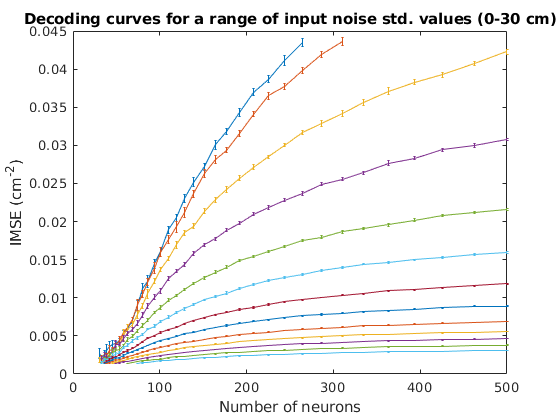

figure;
for i = 1:numel(s_values)
    ep_(n_series{i}, 1./mse_series{i}, '-'); hold on;
end
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
title 'Decoding curves for a range of input noise std. values (0-30 cm)'

#### Figure 5: Decoder performance as a function of ensemble size for a range of input noise values

From the highest to the lowest curve, showing the IMSE of decoding as a function of ensemble size with input noise standard deviations ranging linearly from 0 (highest curve) to 30 cm (lowest curve). The highest curves are clipped just under 0.0453 due to the instability and nonlinearity of our definition of IMSE in that regime. These curves display a variety of saturation rates.

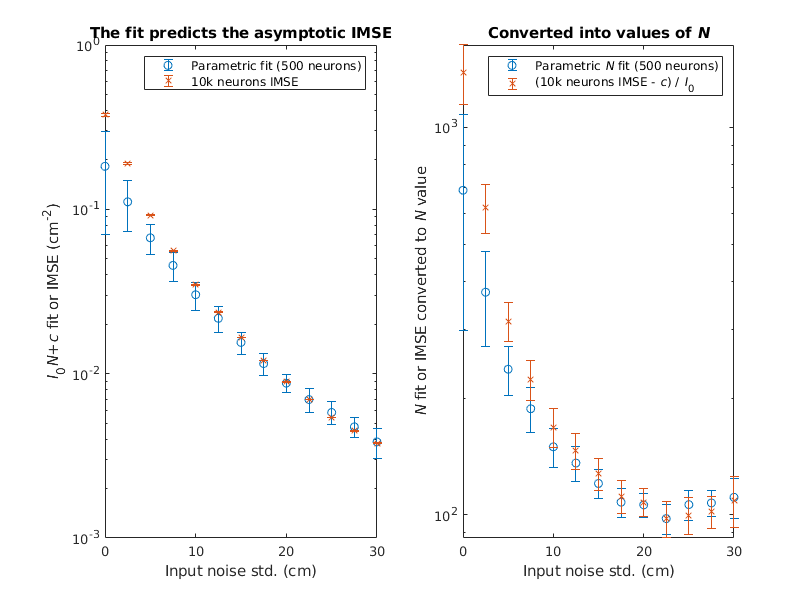

figure('Position', [394   483   811   604]);
subplot(1,2,1);
I0N_series = cellfun(@(x)x.N*x.I_0+x.c, fr_series);
I0N_conf = cellfun(@(x)sqrt((x.I_0*x.N).^2.*((get_ci(x,'N')./x.N).^2 + (get_ci(x,'I_0')./x.I_0).^2) + get_ci(x,'c').^2), fr_series);
errorbar(s_values, I0N_series, I0N_conf, 'o');
hold on;
%x_ = 2:0.01:30;
%plot(x_, to_imse_const./x_.^2);

lim_mean = cellfun(@(x)mean(1./x), limit_mse);
lim_conf = 1.96*cellfun(@(x)std(1./x), limit_mse)./sqrt(cellfun(@numel, limit_mse));

errorbar(s_values, lim_mean, lim_conf, 'x');

%legend 'Curve fit (500 neurons)' 'Predicted from input noise' '10k neurons IMSE'
legend 'Parametric fit (500 neurons)' '10k neurons IMSE'
xlabel 'Input noise std. (cm)'
ylabel('{\itI}_0{\itN}+{\itc} fit or IMSE (cm^{-2})')
set(gca, 'YScale', 'log')
title 'The fit predicts the asymptotic IMSE'
subplot(1,2,2);
N_series = cellfun(@(x)x.N, fr_series);
N_conf = cellfun(@(x)get_ci(x,'N'), fr_series);
errorbar(s_values, N_series, N_conf, 'o');
hold on;
v_ = @(v)cellfun(@(x)x.(v), fr_series);
c_ = @(v) cellfun(@(x) get_ci(x,v), fr_series);
errorbar(s_values, (lim_mean - v_('c'))./v_('I_0'),...
    abs((lim_mean - v_('c'))./v_('I_0')).*sqrt((lim_conf.^2 + c_('c').^2)./(lim_mean - v_('c')).^2 + c_('I_0').^2./v_('I_0').^2), 'x');
set(gca, 'YScale', 'log');
legend 'Parametric {\itN} fit (500 neurons)' '(10k neurons IMSE - {\itc}) / {\itI}_0'
xlabel 'Input noise std. (cm)'
ylabel('{\itN} fit or IMSE converted to {\itN} value')
title 'Converted into values of {\itN}'

#### Figure 6: The extrapolated asymptotic decoder performance using 500 neurons coincides with the decoder's performance with a 10,000 neuron ensemble above a 7.5cm stdev. input noise level.

**(Left) **The estimates of the asymptotic decoder accuracy, derived from the parametric fits on the 500 neuron ensemble ($I_{0\;} N+c$, blue). The confidence intervals of these values coindice with those of the IMSE of a 10,000 neuron ensemble with the same input noise level, given an input noise stdev. above ~7.5cm. Otherwise, the projected values are underestimates. The confidence intervals of the parameters have been propagated accordingly.

**(Right) **The estimates of the parameter *N, *derived from the parametric fits on the 500 neuron ensemble (blue). The confidence intervals of these values coincide with those of $\frac{\left({\textrm{IMSE}}_{10k} -c\right)}{I_0 }$, where ${\textrm{IMSE}}_{10k}$ is the IMSE of a 10,000 neuron ensemble with the same input noise level, given an input noise stdev. above ~7.5cm. Otherwise, the projected *N* values are underestimates. The confidence intervals of the parameters have been propagated accordingly.

## Appendix A: Determining where the IMSE metric of decoder performance is linear with respect to the variance of the input noise

The simulated datasets have a parameter that we can vary freely, namely, the common input noise to all the neurons. In the limit of infinite neurons, the decoding accuracy of the ensemble should match the accuracy of the common input noise. We can simulate that scenario by having just one neuron that only has input noise but no output noise. The accuracy corresponding to the variance of the input noise should match the IMSE accuracy (Fig. A1).

Instead of referring to the input noise level by its standard deviation, we will refer to it by its inverse variance, or inverse input variance (IIV), which is analogous to the IMSE.

sigma_vals = logspace(-1,4,150);
rmse_vals = arrayfun(@sigma2rmse, sigma_vals);

sigma2rmse(10)

ans = 4.6886

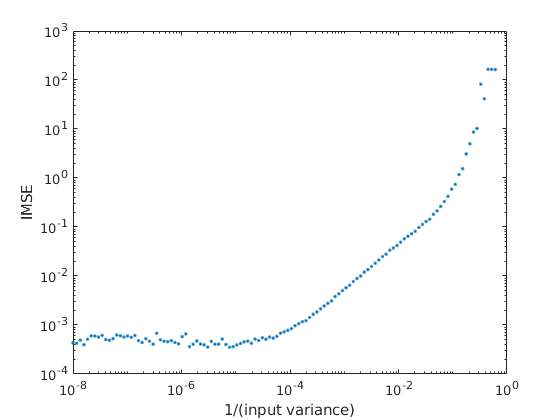

figure;
loglog(1./sigma_vals.^2, 1./rmse_vals.^2, '.');
xlabel '1/(input variance)'
ylabel 'IMSE'

#### Figure A1: The IMSE is consistent with the IIV only in a certain regime

Using a model of one noiseless rate-coding neuron, and a decoder based on linear discriminant analysis (LDA), we establish the connection between the input noise, characterized by its inverse variance (x-axis) and the IMSE of decoding (y-axis). With low IIV (high input noise), the IMSE becomes insensitive since it reaches the maximal possible error. With high IIV (low input noise), the IMSE becomes super-linear due to the discretization of position into 20 bins. We focused our analysis on the linear regime.

We can see that there is a linear correspondence between 1e-4 and 0.01 inverse input variance (Fig. A1).

low_IIV_bound = 1e-4

low_IIV_bound = 1.0000e-04

high_IIV_bound = 0.01

high_IIV_bound = 0.0100

Converting the IIV boundary values into IMSE boundary values, we find the following bounds:

low_IMSE_bound = iiv2imse(low_IIV_bound)

low_IMSE_bound = 7.8802e-04

high_IMSE_bound = iiv2imse(high_IIV_bound)

high_IMSE_bound = 0.0453

Next, we verify that the putative linear regime is indeed linear, by fitting a linear model (Fig. A2).

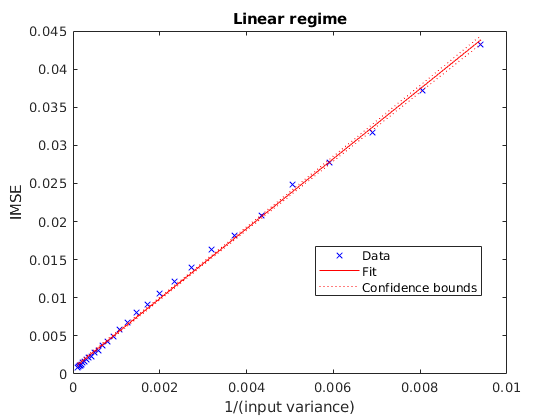

[iiv_vals, ord] = sort(1./sigma_vals.^2);
imse_vals = 1./rmse_vals(ord).^2;

linear_range_begin = find(iiv_vals > low_IIV_bound, 1);
linear_range_end = find(iiv_vals > high_IIV_bound, 1) - 1;

iiv_vals = iiv_vals(linear_range_begin:linear_range_end);
imse_vals = imse_vals(linear_range_begin:linear_range_end);

mdl = fitlm(iiv_vals, imse_vals);
figure;
plot(mdl);
xlabel '1/(input variance)'
ylabel 'IMSE'
title 'Linear regime'

#### Figure A2: Fitting a linear model to the linear regime of the IIV-IMSE relation

We took the IIV values and their corresponding IMSE values within the linear regime from Fig. A1, and fitted a linear model between them. Unlike in Fig. A1, these values are plotted on a linear scale.

mdl

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)    0.00072557    0.00011522    6.2971    8.2597e-07
    x1                 4.5879      0.034618    132.53    1.0019e-40


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.000479
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 1.76e+04, p-value = 1e-40

to_imse_const = mdl.Coefficients.Estimate(2)

to_imse_const = 4.5879

The relationship is nearly proportional, with a constant of ~4.5. We will only fit curves to IMSE values that are within the linear regime of [7.8802e-4 - 0.0453], otherwise the model equation of $I\left(n\right)=\frac{I_0 n}{1+\frac{n}{N}}+c$ is not theoretically justified.

function rmse = sigma2rmse(sigma)
[~, mse] = general_decoding_curve('noise_sigma', sigma,...
    'approx_samp', 1,...
    'n_reps', 1,...
    'n_cells', 1,...
    'response_type', "gaussian",...
    'model_type', "rate coding",...
    'progress', false); 
rmse = sqrt(mean(mse));
end

function imse = iiv2imse(iiv)
sigma = 1./sqrt(iiv);
rmse = sigma2rmse(sigma);
imse = 1./rmse.^2;
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end

function ep_(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none");
end

function ci = get_ci(fit_mdl, varname)
names = coeffnames(fit_mdl);
idx = find(strcmp(names, varname));
assert(numel(idx) == 1, 'Variable not found');

q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end